# **Getting Started with MATVISA**

## System Requirements

MATVISA only works for computers running **Windows** with the **.NET Framework **installed. The MATLAB .NET environment also needs to be set to "Framework". Click the 'Run' button in the code block below to check your compatibilty.

% make sure .NET is support on your computer
assert(NET.isNETSupported, ...
    ".NET is not supported on this computer, probably because it's not using Windows");
% make sure MATLAB is using the .NET framework
assert(string(dotnetenv().Runtime) == "framework", ...
    "MATLAB is not using the .NET framework. See matlab dotnetenv() for help");
% make sure you have NI-VISA installed
try
    NET.addAssembly("NationalInstruments.Visa");
catch
    error("It looks like you don't have NI-VISA installed." + newline + ...
        "www.ni.com/en/support/downloads/drivers/download.ni-visa.html");
end
% celebrate if we made it here
disp("You're good to go!")
 

## Finding Instruments

You can use "`matvisa.find()" to list all instruments connected to your computer. If you don't see your instrument here, check your Windows Device Manager. You might need to install a driver from the instrument manufacturer.`

% list all instruments connected to your computer
% note: find() will throw an ERROR if no instrument is found
resource_ids = matvisa.find()
 

You can also use a flavor of regular expressions to look for a particular instrument.

filtered_ids = matvisa.find("ASRL?*") % - all available serial ports
% matvisa.find("USB::?*")  - all USB instruments
% matvisa.find("GPIB::?*") - all GPIB instruments, etc...
 

For more information on these regular expressions, see the IVI VISA Library documentation:

[www.ivifoundation.org/specifications/default.html#visa-specifications](http://www.ivifoundation.org/specifications/default.html#visa-specifications)

## Connecting to an Instrument

To connect to an instrument, pass its resource ID to `matvisa(). Use the dropdown menu below to select your instrument. If your instrument is connected via serial port, you'll also want to select a baud rate and terminator. The terminator is a character(s) used to separate commands. The default MATVISA baud rate is 9600 and default terminator is \n.`

my_instrument = matvisa(resource_ids(1))
my_instrument.terminator = newline; % note: if you want CRLF, use sprintf("\r\n")
try my_instrument.baud = 9600; catch; end

**WARNING**: If you forget to use `sprintf()` and just set the terminator equal to `"\r\n"`, `matvisa()` will assume you're *literally* using all 4 of those characters for termination.

## Reading and Writing Strings

The list of commands an instrument can support varies widely, but most 488.2 compliant instruments implement a `*RST` command to reset your instrument to a default state.

To send an SCPI command to your instrument, use the `writeline()` method.

scpi_command  = "*RST";
my_instrument.writeline(scpi_command); % sends <scpi_command> + <terminator>
 

Hopefully this makes some lights flash, relays click, or loading wheels spin so you know it worked.

Most instruments also support the *IDN? query, which returns the manufacturer's  ID string. We'll use `writeline()` to send the query to the instrument, and `readline()` to get the instrument's response.

scpi_query  = "*IDN?";
my_instrument.writeline(scpi_query);
response1 = my_instrument.readline() % stops read at <terminator> OR <488.2 END>
 

Because the `writeline() readline()` workflow is probably going to be 99% of your instrument control script, MATVISA provides a shorter alias for it, `query()`.

response2 = my_instrument.query(scpi_query) % equivilent to writeline(), readline()
 

## Reading and Writing Data

To send raw data to your instrument, use the `write()` method. To read raw data, use the `read()` method. 

The `write()` method will send a character array (char / uint8) to the instrument unaltered. This means that, if your instrument requires a terminator, you'll need to append it manually. Note that 488.2 instruments will signal an end-of-message regardless of the terminator.

The `read(n)` method will read `n` bytes from the instrument OR until a 488.2 END indicator is reached. The `read() `method returns the data as an array of characters (char / uint8).

% Read a 488.2 binary block from the instrument
assert(obj.read(1) == '#', "first character was not '#'");
len_meta = obj.read(1);          % "5" as string
len_meta = str2double(len_meta); % 5 as double
len = obj.read(len_meta);        % "50000" as string
len = str2double(len);           % 50000 as double
bytes = obj.read(len);           % The binary data

## Reading and Writing Binary Blocks

To write binary blocks to your instrument, convert your data to `char`/ `uint8` and pass it to the `writebinblock()` method. The `writebinblock() method will append a 488.2 header to your data pass it to write().`

% write a binary block to your instrument
my_data = rand(1,100);
my_instrument.writebinblock(my_data); % will write '#3100<my_data>'

To read binary blocks from your instrument, use the `readbinblock()` method. The `readbinblock()` method will remove the incoming binary block header and return the raw data as the `char type`. Note, you will likely need to use MATLAB's `typecast()` and `swapbytes()` functiond on the returned data to reassemble it.

% get some waveform data from your instrument
obj.write("WAVEFORM:DATA?");
my_data = obj.readbinblock();
my_data = typecast(my_data, 'int16');
my_data = swapbytes(my_data); % you may or may not need to do this

## Flushing I/O Buffers

If you perform a partial read, you'll probably want to cleanup the I/O buffers with the `flush()` method.

my_instrument.writeline(scpi_query);
first_four = my_instrument.read(4); % returns 'KEYS' for my Keysight scope
my_instrument.flush();

## Example Instrument Class

MATVISA contains an example instrument class called `EDUX1052G() for the Keysight EDUX1052G oscilloscope`. You can view the class by calling MATLAB's `edit()` function.

edit EDUX1052G.m
 

An example program using this class might look like this:

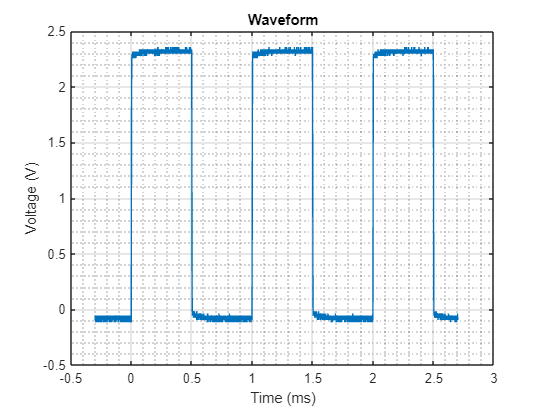

% connect to the scope
instrument_id = matvisa.find("USB?*"); % if this is your only USB instrument
scope = EDUX1052G(instrument_id);      % EDUX1052G inherits the matvisa constructor
scope.flush();                         % a good 'just-in-case' practice
scope.reset();                         % start in a known state

% setup the trigger
scope.trigger_sweep = "NORM";          % only trigger when conditions are met
scope.trigger_edge_level = 1;          % 1V is fine for the demo signal

% setup the timebase
scope.timebase_reference = "LEFT";     % personal preference
scope.timebase_range = 3e-3;           % 3ms is 3 cycles of the demo signal

% setup channel 1
scope.channel_display(1) = true;       % make sure channel 1 is on
scope.channel_scale(1) = 500E-3;       % get the best resolution out of our signal
scope.channel_offset = 1.25;           % move the waveform down so it fits

% capture the demo signal
scope.single();
while(scope.is_armed == false); end    % wait for the trigger to arm
while(scope.is_running == true); end   % wait for the scope to come to a stop
scope.waveform_source = "CHAN1";       % this is the channel to pull data from
scope.waveform_format = "WORD";        % transfer the data as int16's
my_data = scope.waveform_data;         % retreive the data

% plot the waveform
plot(milliseconds(my_data.time), my_data.voltage);
title Waveform
xlabel 'Time (ms)'
ylabel 'Voltage (V)'
grid on
grid minor

## Doing Fancy Things

If you're trying to do some low-level VISA shenanigans that MATVISA doesn't expose in its API, be my guest. MATVISA makes the NI-VISA library avalable to MATLAB when it runs:

NET.addAssembly("NationalInstruments.Visa");

The instrument's NI-VISA session is a public property of all `matvisa` objects, called `visa`.

my_instrument.visa.AssertTrigger(); % send a software trigger to the instrument

You can also access anything in the `NationalInstruments.Visa` libary directly in MATLAB.

rm = NationalInstruments.Visa.ResourceManager();

Click the button below to open the NI-VISA documentation installed with your copy of NI-VISA

doc = dir("C:\Program Files\IVI Foundation\VISA" + ...
    "\Microsoft.NET\Framework64\**\NINETVISA.chm");
system(['explorer "' doc.folder '\' doc.name '"']);
 